# Regularized Zero Forcing Precoder

% Downlink
% Rate V.S. Power
% Linear Formation and Rectangular Formation

## Global Parameter

clc
clearvars

K = 10;
M1 = 8;
M2 = 8;
M = M1 * M2;

taps = 4;
freq = 20;

use = 5;

time = 100;
cyclic_prefix = 20;
shield = taps + freq + 1;

points = 400;

r = logspace(-2, 2, points);
e = 10 * log10(r);

IK = eye(K);

dn = 0.5;

alpha = 0.99;
eta = 500;
mu = 0;


## Distance Matrix and Correlation

for i = 1 : M
    for j = 1 : M
        dist(i, j) = abs(i - j) * dn;
    end
end
exp_1D = alpha .^ dist;
arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_1D = abs(besseli(0, arg) ./ besseli(0, eta));
clear dist;

i = 1;
for c1 = 1 : M1
    for r1 = 1 : M2
        j = 1;
        for c2 = 1 : M1
            for r2 = 1 : M2
                dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                j = j + 1;
            end
        end
        i = i + 1;
    end
end
dist = sqrt(dist .* dn);
arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_2D = abs(besseli(0, arg) ./ besseli(0, eta));
exp_2D = alpha .^ dist;
clear dist;


## Channel Power Delay Profile

u = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end

## Search Tree

for n = 1 : use
    S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
    Z(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));

    for l = 1 : taps
        D1 = D(:, :, l) .^ (0.5);
        H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
        
        Hl_exp_1D(:, :, l, n) = conj((exp_1D ^ (0.5)) * H1) * D1;
        Hl_bsl_1D(:, :, l, n) = conj((bsl_1D ^ (0.5)) * H1) * D1;
        Hl_exp_2D(:, :, l, n) = conj((exp_2D ^ (0.5)) * H1) * D1;
        Hl_bsl_2D(:, :, l, n) = conj((bsl_2D ^ (0.5)) * H1) * D1;
    end
    
    Hv1 = fft(Hl_exp_1D(:, :, :, n), freq, 3);
    Hv2 = fft(Hl_bsl_1D(:, :, :, n), freq, 3);
    Hv3 = fft(Hl_exp_2D(:, :, :, n), freq, 3);
    Hv4 = fft(Hl_bsl_2D(:, :, :, n), freq, 3);
    bp = 2;
    if (0 <= alpha) && (alpha < 0.4)
        bp = 10;
    elseif (0.4 <= alpha) && (alpha < 0.7)
        bp = 10.7;
    elseif (0.7 <= alpha) && (alpha < 0.9)
        bp = 8.5;
    elseif (0.9 <= alpha) && (alpha < 0.99)
        bp = 2;
    else
        bp = 0.5;
    end
    for v = 1 : freq
        Fv = Hv1(:, :, v);
        Wv1(:, :, v) = Fv / (Fv' * Fv + bp * IK);
        clear Fv;
        Fv = Hv2(:, :, v);
        Wv2(:, :, v) = Fv / (Fv' * Fv + bp * IK);
        clear Fv;
        Fv = Hv3(:, :, v);
        Wv3(:, :, v) = Fv / (Fv' * Fv + bp * IK);
        clear Fv;
        Fv = Hv4(:, :, v);
        Wv4(:, :, v) = Fv / (Fv' * Fv + bp * IK);
        clear Fv;
    end
    Wl_exp_1D(:, :, :, n) = ifft(Wv1, freq, 3);
    Wl_bsl_1D(:, :, :, n) = ifft(Wv2, freq, 3);
    Wl_exp_2D(:, :, :, n) = ifft(Wv3, freq, 3);
    Wl_bsl_2D(:, :, :, n) = ifft(Wv4, freq, 3);

    [AX1(n)] = Signal_Power(freq, Wl_exp_1D(:, :, :, n));
    [AX2(n)] = Signal_Power(freq, Wl_bsl_1D(:, :, :, n));
    [AX3(n)] = Signal_Power(freq, Wl_exp_2D(:, :, :, n));
    [AX4(n)] = Signal_Power(freq, Wl_bsl_2D(:, :, :, n));
    
    for k = 1 : K
        for l = 0 : (taps - 1)
            V1 = Hl_exp_1D(:, :, l + 1, n) * IK(:, k);
            V2 = Wl_exp_1D(:, :, l + 1, n) * IK(:, k);
            X1(l + 1) = V1' * V2;
            clear V1;
            clear V2;
            V1 = Hl_bsl_1D(:, :, l + 1, n) * IK(:, k);
            V2 = Wl_bsl_1D(:, :, l + 1, n) * IK(:, k);
            X2(l + 1) = V1' * V2;
            clear V1;
            clear V2;
            V1 = Hl_exp_2D(:, :, l + 1, n) * IK(:, k);
            V2 = Wl_exp_2D(:, :, l + 1, n) * IK(:, k);
            X3(l + 1) = V1' * V2;
            clear V1;
            clear V2;
            V1 = Hl_bsl_2D(:, :, l + 1, n) * IK(:, k);
            V2 = Wl_bsl_2D(:, :, l + 1, n) * IK(:, k);
            X4(l + 1) = V1' * V2;
            clear V1;
            clear V2;
        end
        EX1(k, n) = sum(X1);
        clear X1;
        EX2(k, n) = sum(X2);
        clear X2;
        EX3(k, n) = sum(X3);
        clear X3;
        EX4(k, n) = sum(X4);
        clear X4;
    end
end
a1 = mean(AX1);
a2 = mean(AX2);
a3 = mean(AX3);
a4 = mean(AX4);

Y1 = zeros(K, time, use);
Y2 = zeros(K, time, use);
Y3 = zeros(K, time, use);
Y4 = zeros(K, time, use);
for n = 1 : use
    for k = 1 : K
        for l = 0 : (taps - 1)
            V1 = Hl_exp_1D(:, :, l + 1, n) * IK(:, k);
            V2 = Hl_bsl_1D(:, :, l + 1, n) * IK(:, k);
            V3 = Hl_exp_2D(:, :, l + 1, n) * IK(:, k);
            V4 = Hl_bsl_2D(:, :, l + 1, n) * IK(:, k);
            for m = 0: (freq - 1)
                V5 = Wl_exp_1D(:, :, m + 1, n);
                V6 = Wl_bsl_1D(:, :, m + 1, n);
                V7 = Wl_exp_2D(:, :, m + 1, n);
                V8 = Wl_bsl_2D(:, :, m + 1, n);
                Y1(k, shield: time, n) = Y1(k, shield: time, n) + (V1' * V5 * S(:, (shield : time) - m - l, n));
                Y2(k, shield: time, n) = Y2(k, shield: time, n) + (V2' * V6 * S(:, (shield : time) - m - l, n));
                Y3(k, shield: time, n) = Y3(k, shield: time, n) + (V3' * V7 * S(:, (shield : time) - m - l, n));
                Y4(k, shield: time, n) = Y4(k, shield: time, n) + (V4' * V8 * S(:, (shield : time) - m - l, n));
            end
        end
        X1(k, 1: time, n) = mean(EX1(k, :)) * S(k, 1 : time, n) / a1;
        X2(k, 1: time, n) = mean(EX2(k, :)) * S(k, 1 : time, n) / a2;
        X3(k, 1: time, n) = mean(EX3(k, :)) * S(k, 1 : time, n) / a3;
        X4(k, 1: time, n) = mean(EX4(k, :)) * S(k, 1 : time, n) / a4;
    end
end

Z1(:, 1 : (shield - 1), :) = (Y1(:, 1 : (shield - 1), :) / a1);
Z1(:, shield : time, :) = (Y1(:, shield : time, :) / a1) - X1(:, shield : time, :);
Z2(:, 1 : (shield - 1), :) = (Y2(:, 1 : (shield - 1), :) / a2);
Z2(:, shield : time, :) = (Y2(:, shield : time, :) / a2) - X2(:, shield : time, :);
Z3(:, 1 : (shield - 1), :) = (Y3(:, 1 : (shield - 1), :) / a3);
Z3(:, shield : time, :) = (Y3(:, shield : time, :) / a3) - X3(:, shield : time, :);
Z4(:, 1 : (shield - 1), :) = (Y4(:, 1 : (shield - 1), :) / a4);
Z4(:, shield : time, :) = (Y4(:, shield : time, :) / a4) - X4(:, shield : time, :);

for n = 1 : use
    for k = 1 : K
        Sn1 = r * mean(abs(X1(k, :, n)) .^ 2);
        Sn2 = r * mean(abs(X2(k, :, n)) .^ 2);
        Sn3 = r * mean(abs(X3(k, :, n)) .^ 2);
        Sn4 = r * mean(abs(X4(k, :, n)) .^ 2);
        
        Vn1 = r * mean(abs(Z1(k, :, n)) .^ 2) + 1;
        Vn2 = r * mean(abs(Z2(k, :, n)) .^ 2) + 1;
        Vn3 = r * mean(abs(Z3(k, :, n)) .^ 2) + 1;
        Vn4 = r * mean(abs(Z4(k, :, n)) .^ 2) + 1;
        
        SNR1 = Sn1 ./ Vn1;
        SNR2 = Sn2 ./ Vn2;
        SNR3 = Sn3 ./ Vn3;
        SNR4 = Sn4 ./ Vn4;
        
        Rk1(:, k, n) = 0.5 * log2(1 + SNR1);
        Rk2(:, k, n) = 0.5 * log2(1 + SNR2);
        Rk3(:, k, n) = 0.5 * log2(1 + SNR3);
        Rk4(:, k, n) = 0.5 * log2(1 + SNR4);
    end
end

R1 = mean(sum(Rk1, 2), 3);
R2 = mean(sum(Rk2, 2), 3);
R3 = mean(sum(Rk3, 2), 3);
R4 = mean(sum(Rk4, 2), 3);

Sn0 = (M / K) * r;
Vn0 = r + 1;
SNR0 = Sn0 ./ Vn0;
C0 = (K / 2) * log2(1 + Sn0);
R0 = (K / 2) * log2(1 + SNR0);

factor = (time) / (time + cyclic_prefix);

R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;


## Visualization

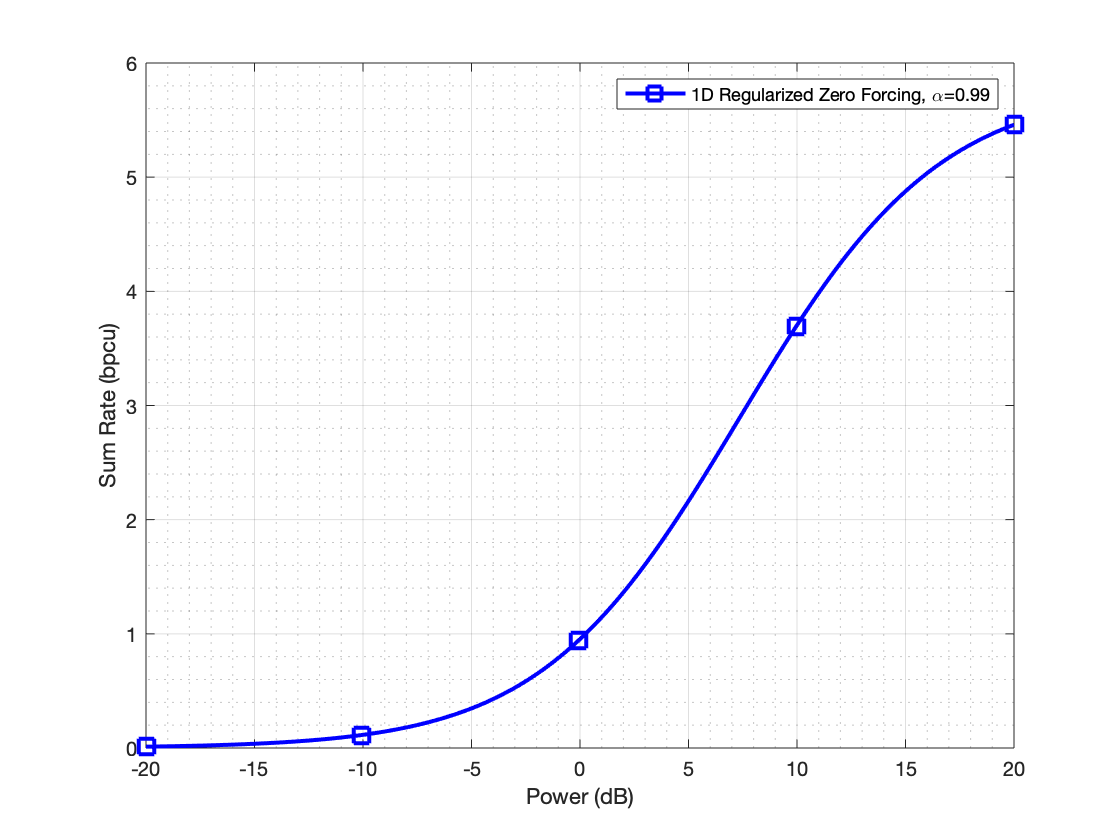

index = [1, 100, 200, 300, 400];

angel = strcat('\pi/', num2str(pi / mu));
if (mu == 0)
    angel = num2str(0);
end

name_a = '1D Regularized Zero Forcing';
name_b = '2D Regularized Zero Forcing';

name1 = strcat(name_a, ', \alpha=', num2str(alpha));
% name2 = strcat(name_a, ', \eta=', num2str(eta), ', \mu=', angel);
name2 = strcat(name_a, ', \eta=', num2str(eta));
name3 = strcat(name_b, ', \alpha=', num2str(alpha));
% name4 = strcat(name_b, ', \eta=', num2str(eta), ', \mu=', angel);
name4 = strcat(name_b, ', \eta=', num2str(eta));

x_label = 'Power (dB)';
y_label = 'Sum Rate (bpcu)';

style = '-bs';

figure;
plot(e, R1, style, 'DisplayName', name1, 'MarkerIndices', index, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

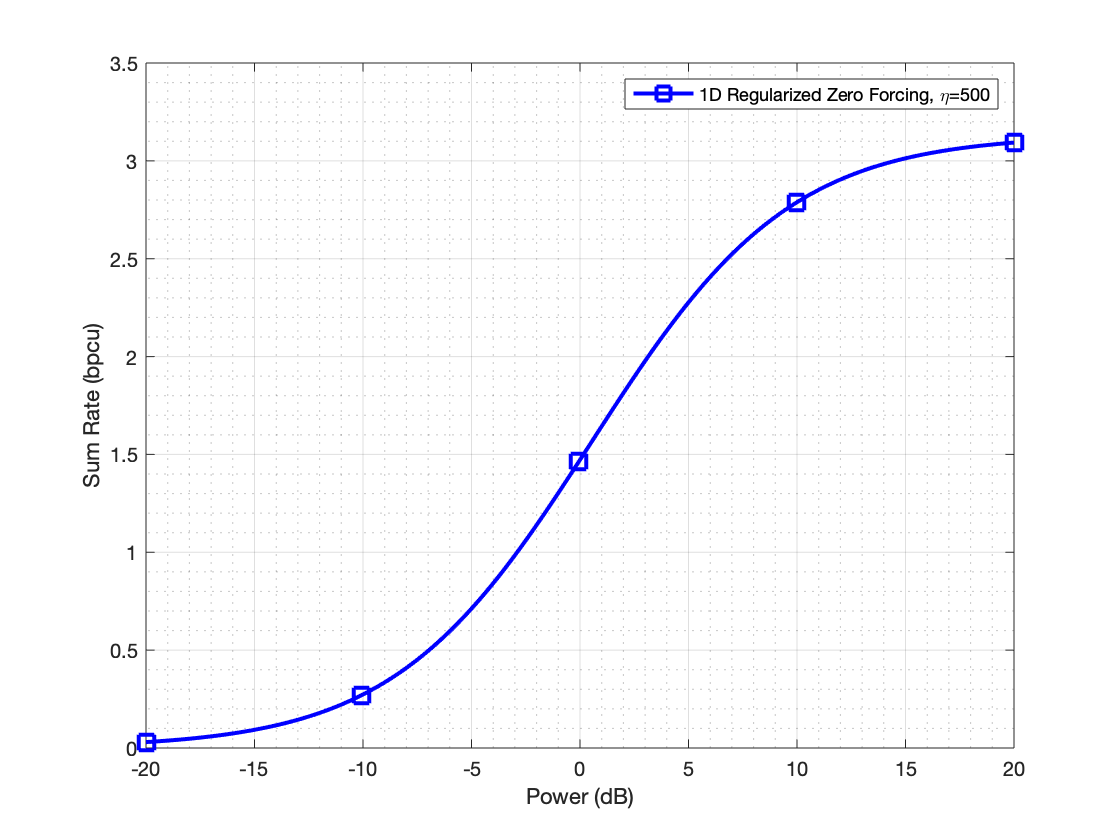



figure;
plot(e, R2, style, 'DisplayName', name2, 'MarkerIndices', index, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

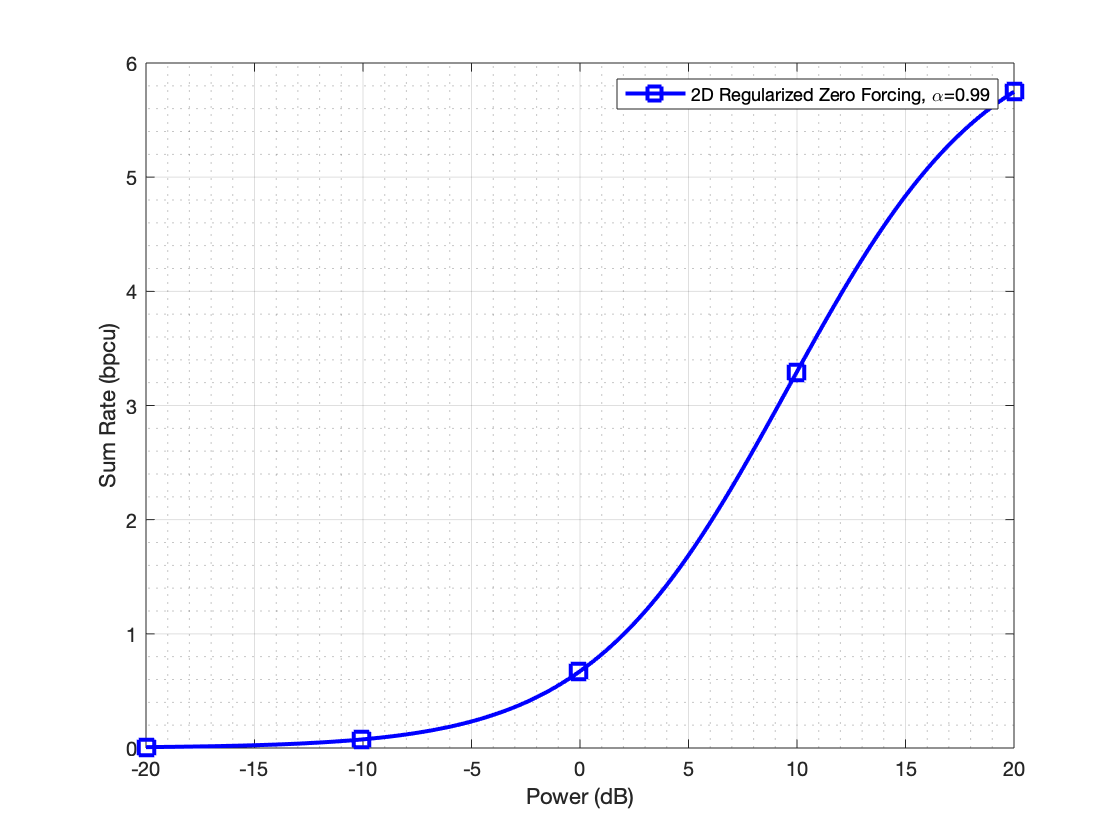


figure;
plot(e, R3, style, 'DisplayName', name3, 'MarkerIndices', index, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

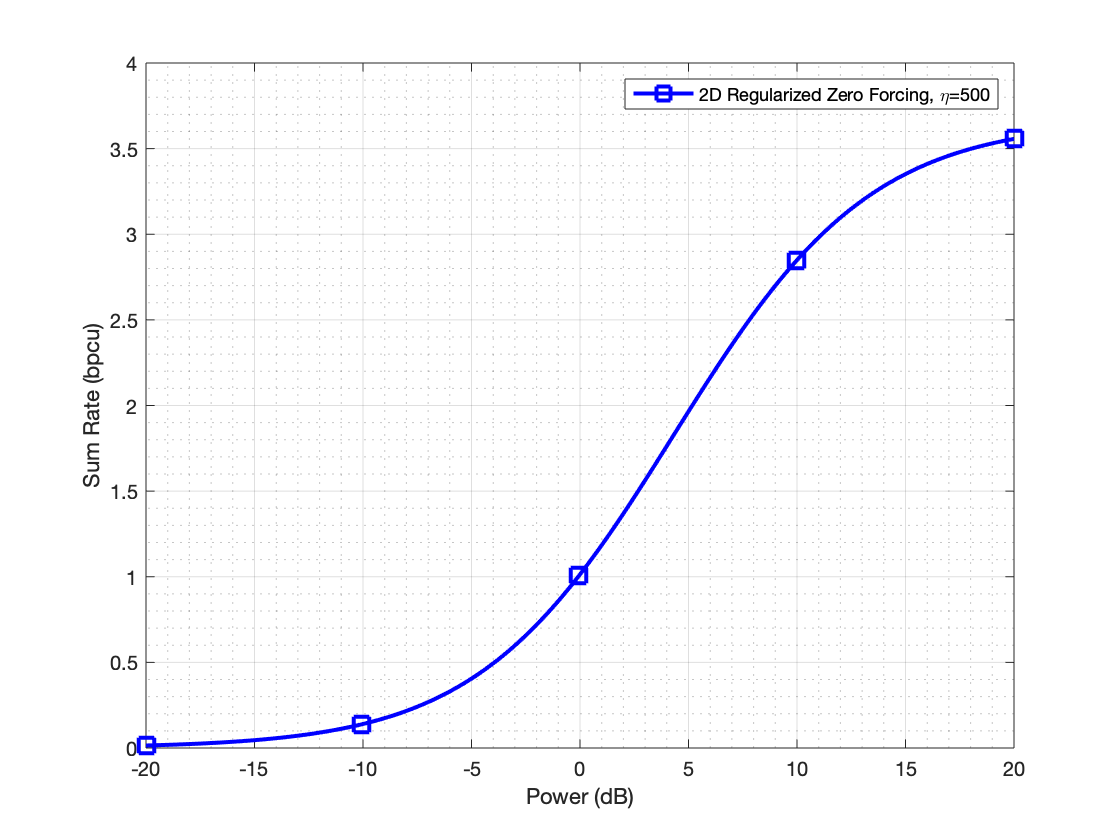



figure;
plot(e, R4, style, 'DisplayName', name4', 'MarkerIndices', index, 'MarkerSize', 10);

ylabel(y_label, 'fontsize', 10);
xlabel(x_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;